# **DBT** Projektwoche WS20/21

`Defekt-Cluster-Korrektur nach dem Verfahren von Efros & Leung (1997)`

`Maria Shishkina (11103525)`

`------------------------------`

clear
addpath(genpath(pwd()));

## Einlesen der Textur

Die Textur kann automatisch oder manuell gewählt werden:

pat_selection = "auto";

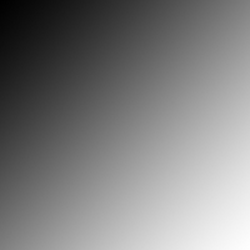

PAT/pat02.tif


switch pat_selection
    case 'auto'
        pattern_list = dir('PAT/pat*.*');
        fpath=fullfile('PAT', pattern_list(randi(numel(pattern_list))).name);
    case 'eigen'
        default_pat='PAT/pat01.tif';
        [file, path] = uigetfile({'PAT/*.*'}, 'Select a pattern', default_pat);
        if file ~= 0
            fpath = [path file];
        else
            fpath = default_pat;
        end
end

[I, ~] = patRead(fpath); imdisplay(I, 'Original image'); disp(fpath);

[Iheight, Iwidth] = size(I);

 


## Parametereinstellung

roiSize = 9; roi_half = floor(roiSize/2);
windowSize = 31; win_half= floor(windowSize/2);
scale = "log";
 

[I, ~] = patRead(fpath);
switch scale
    case 'linear'
        % bereits linear
    case 'log'
        I = log(I+1);
        invI = @(x) exp(x)-1;
    case 'gamma'
        gamma=2.2;
        I = imadjust(I,[],[],(1/gamma));
end

## Defekte Cluster zufügen

Man beachte, dass in der Maske **die Defektcluster **mit 1 gekennzeichnet sind, und die gültigen Pixel mit 0 (im Gegensatz zu den gängigen Verfahren). Finde ich intuitiver -- sorry!

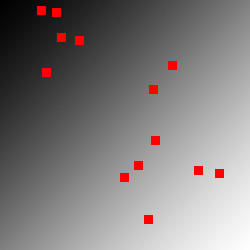

 

clusterSize =9;
numDefects = 13;

mask = pxDecay(I, 'ClusterSize', clusterSize, 'ROISize', roiSize, 'NumDefects', numDefects);
imdisplay(imoverlay(invI(I), mask, 'red'));

mask_copy = mask;

## Summum opus

Eine wiederholte Nutzung ist möglich -- ab hier kann man die Synthhese durch mehrere Iterationen mit "Run to End" derselben Maske und des Bildes überprüfen

I_new = I.*(~mask_copy);
%I_temp = I_new;
mask=mask_copy;

Geduldsprobe: falls die Pixel keine Übereinstimmung in dem ersten Durchlauf bekamen, kann man diese später überprüfen, wenn sie bereits "gültige" Nachbarn besitzen. Jedes Pixel bekommt einen Zähler, und Pixel, die die Anzahl der Iterationen überschritten haben, werden endgültig aufgegeben.

*[ **Anmerkung**: Solche drastischen Maßnahmen (und Zahlen) nur, weil ich es nicht belassen kann und mit extern angefertigten Bitmap-Masken und Wachstum nach außen experimentiere ]*

snd = {}; patience = zeros(size(I));
max_no_iterations = 113;

Solange die Maske Defektpixel hat, werden diese regionenweise untersucht. Man fange am Clusterrand an, d.h. an den Stellen mit den meisten bekannten Nachbarn, und lese die Grenzpixel der Regionen in der Binärmaske aus.

while any(any(mask))
    bb = bwboundaries(mask);
    
    for j=1:numel(bb)
        region = cell2mat(bb(j));

    Erste und letzte Elemente der Region wiederholen sich, selbst wenn sie aus nur einem Pixel besteht -- die Funktion `bwboundaries()` betrachtet das Ganze als eine Art Bounding Box. In Regionen größer als 1px werden die Pixel gemischt und in zufälliger Reihenfolge betrachtet. Wenn man die Kante in einer strikten Richtung betrachtet, muss man darauf achten, das die neulich zugewiesenen Pixel bei den direkten Nachbarn zur Fehlerkennung führen können, und jede Iteration in einer temporären Struktur zwischenspeichern. Die `randperm()`-Funktionen sind pseudozufällig, meistens sogar mit einer äquidistanten Verteilung -- die Berechnung wird vor allem bei größeren Clusters sehr individuell.

        region=region(1:end-1,:);
        if numel(region(:,1)) > 1
            region=region(randperm(length(region)),:);
        end
        for k=1:size(region,1)
            pix = region(k,:);
            
            [roi, mask_roi, roiBig, mask_roiBig] = blocParty(pix, I_new, mask, roi_half, win_half);
            
            [prediction, err] = ssd(roi, roiBig, mask_roi, mask_roiBig);
            
            if ~err
                I_new(pix(1), pix(2)) = prediction; %I_temp(pix(1), pix(2)) = prediction;
            else
                snd{end+1}=pix;
                patience(pix(1), pix(2)) = patience(pix(1), pix(2)) + 1;
                continue
            end
            
        end
    end

Alle Kantenpixel werden für "behandelt" erklärt und werden von der Maske via Erosion gelöscht. Diejenigen, die eigentlich nicht bestimmt worden sind, sind in `snd` gespeichert worden und werden nach der Erosion wieder in die Maske übertragen (für die nächste Distanzbestimmung).

    mask = imerode(mask, true(3));
    
    while ~isempty(snd)
        ch = snd{:,1};
        if patience(ch(1),ch(2)) <= max_no_iterations
            mask(ch(1),ch(2)) = 1;
        end
        snd=snd(2:end);
    end
    
    % I_new = I_temp;
end

### Ende

Rückwandlung in den intensitätsslinearen Skalenraum und Gegenüberstellung des defekten Bildes mit dem synthetisierten:

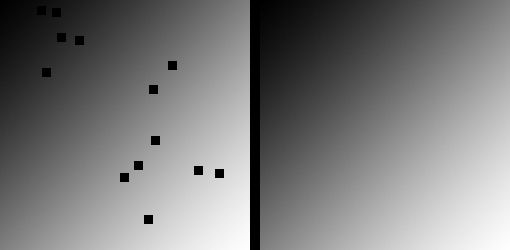

if scale == "log"
    I = invI(I);
    I_new = invI(I_new);
elseif scale == "gamma"
    I = imadjust(I,[],[],(gamma));
    I_new = imadjust(I_new,[],[],(gamma));
end
scale = "linear";

imdisplay([I.*(~mask_copy), zeros(size(I_new,1),10), I_new]);

## Ähnlichkeitsmetriken

#### Mean Absolute Error (MAE)

disp(meanabsolute(I_new, I))

    4.022e-05


#### **Mean Squared Error (MSE)**

disp(meansquared(I_new, I))

   2.0989e-07


Weitere Bildbeurteilungsmetriken, die sich mehr auf strukturelle Eigenschaften konzentrieren als auf reine Helligkeitsunterschiede:

[ *Zur Zeit nicht aussagekräftig genug, da die Clusterfläche verhältnisweise klein ist, wären in Theorie aber bei der Arbeit mit größeren Falschregionen und Image Quilting unerlässlich. Ansonsten bietet sich entweder eine separate Betrachtung der Ausschnitte mit den Defektclusters (z.B. über Angaben von *`regionprops()`*) *]

#### Structural Similarity Index Measure (SSIM) 

[ssimval, ssimmap] = ssim(I_new, I);
disp(ssimval)

      0.99982


#### Correlation Coefficient nach Pearson

disp(corr2(I, I_new))

            1
